# Семестр 6. Задание 1. Проекционные методы решения краевой задачи для ОДУ второго порядка. Вариант 11

## Комментарий

Требуется найти решение краевой задачи


$$-\frac{7-x}{8+3x} u'' + \left(1+\frac{x}{3}\right)u' +\left(1-\frac{1}{2} e^{\frac{x}{2}}\right) u = \frac{1}{2} - \frac{x}{3},\ u(-1)=u(1)=0$$


используя следующие методы:

- Метод наименьших квадратов

- Метод коллокации

Решение данной краевой задачи будет иметь вид


$$y^{n}(x)=\sum\limits_{i=1}^n c_i \omega_i(x)$$


где $\omega_1(x),\dots,\omega_n (x)$ - система ЛНЗ функций. 

В нашем случае, в качестве координатной системы будем использовать систему $\omega_j(x) = (1-x^2)P^{(1,1)}_j(x),\ j=1,2\dots$,  где $P^{(1,1)}_n = \frac{(-1)^n}{2^n n!} (1-x^2)^{-1} \frac{d^n}{dx^n}(1-x^2)^{n+1}
$ - полином Якоби

## Точное решение 

Получим точное решение краевой задачи, используя встроенные методы языка Matlab

**Примечание:** см. acc_solution.m

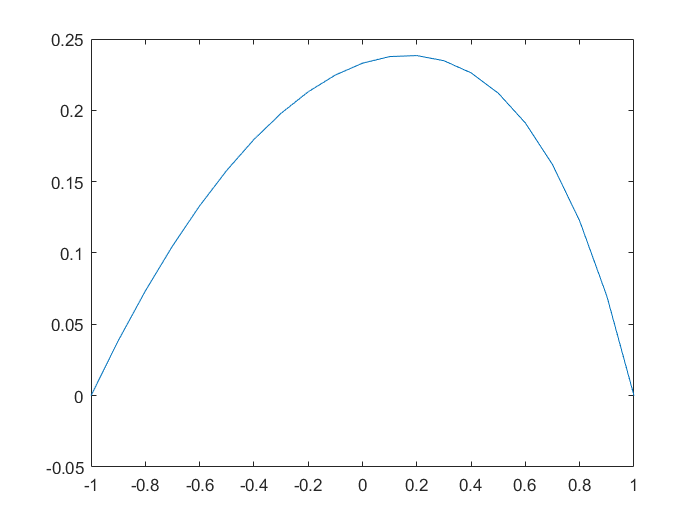

Y_ex = acc_solution;

## Метод наименьших квадратов

### Идея 

Заметим, что решение краевой задачи для нашего уравнения доставляет минимум функционалу $G = (Ly-f, Ly+f)
$. Тогда наша задача сводится к минимизации функционала $G
$, откуда можно получить следующую систему уравнений:


$$\sum\limits_{j=1}^n (L\omega_j,L\omega_i)c_j = (f,L\omega_i),\ i\in 1,\dots, n$$


### Реализация

**Комментарий:** см. min_squares.m

sym f;
syms x;
f = 0.5 - x/3;

% Технические переменные, необходимые для составления таблицы
n_val = zeros(5,1);
cond_A_ms = zeros(5,1);
left_point_val_ms = zeros(5,1);
middle_point_val_ms = zeros(5,1);
right_point_val_ms = zeros(5,1);
left_point_err_ms = zeros(5,1);
middle_point_err_ms = zeros(5,1);
right_point_err_ms = zeros(5,1);

% Поиск различных приближений методом наименьших квадратов
for n=3:7
    n_val(n-2) = n; 
    
    % Создание массива координатных функций
    coordinate_functions = generate_coordinates(n);
    
    % Вычисление значений оператора L на координатных функциях
    L_at_coordinates = L(coordinate_functions);
    
    % Поиск коэффициентов приближения
    [A_ms, b_ms, c_ms] = min_squares(n,L_at_coordinates,f);
    
    % Вывод расширенной матрицы системы на экран
    A_extended = [A_ms,b_ms]
    
    % Вывод коэффициентов приближения на экран
    c_ms
    
    % Заполнение таблицы
    cond_A_ms(n-2) = cond(A_ms,'inf');
    left_point_val_ms(n-2) = value(c_ms,coordinate_functions,-0.5);
    left_point_err_ms(n-2) = Y_ex(6) - left_point_val_ms(n-2); 
    middle_point_val_ms(n-2) = value(c_ms,coordinate_functions,0);
    middle_point_err_ms(n-2) = Y_ex(11) - middle_point_val_ms(n-2); 
    right_point_val_ms(n-2) = value(c_ms,coordinate_functions,0.5);
    right_point_err_ms(n-2) = Y_ex(16) - right_point_val_ms(n-2);   
end

A_extended =    14.3039  -30.5295   37.9031    2.6640
  -30.5295  126.4872 -194.0352   -4.6520
   37.9031 -194.0352  556.6563    8.4409


c_ms =     0.2393
    0.0414
    0.0133


A_extended = 	1.0e+03 *

    0.0143   -0.0305    0.0379   -0.0647    0.0027
   -0.0305    0.1265   -0.1940    0.2814   -0.0047
    0.0379   -0.1940    0.5567   -0.7029    0.0084
   -0.0647    0.2814   -0.7029    1.6636   -0.0099


c_ms =     0.2434
    0.0398
    0.0180
    0.0044


A_extended = 	1.0e+03 *

    0.0143   -0.0305    0.0379   -0.0647    0.0639    0.0027
   -0.0305    0.1265   -0.1940    0.2814   -0.3419   -0.0047
    0.0379   -0.1940    0.5567   -0.7029    1.0382    0.0084
   -0.0647    0.2814   -0.7029    1.6636   -1.8780   -0.0099
    0.0639   -0.3419    1.0382   -1.8780    3.9435    0.0142


c_ms =     0.2444
    0.0392
    0.0167
    0.0053
    0.0012


A_extended = 	1.0e+03 *

    0.0143   -0.0305    0.0379   -0.0647    0.0639   -0.0973    0.0027
   -0.0305    0.1265   -0.1940    0.2814   -0.3419    0.4274   -0.0047
    0.0379   -0.1940    0.5567   -0.7029    1.0382   -1.1031    0.0084
   -0.0647    0.2814   -0.7029    1.6636   -1.8780    2.7529   -0.0099
    0.0639   -0.3419    1.0382   -1.8780    3.9435   -4.1490    0.0142
   -0.0973    0.4274   -1.1031    2.7529   -4.1490    8.0296   -0.0149


c_ms =     0.2445
    0.0392
    0.0164
    0.0049
    0.0014
    0.0003


A_extended = 	1.0e+04 *

    0.0014   -0.0031    0.0038   -0.0065    0.0064   -0.0097    0.0090    0.0003
   -0.0031    0.0126   -0.0194    0.0281   -0.0342    0.0427   -0.0480   -0.0005
    0.0038   -0.0194    0.0557   -0.0703    0.1038   -0.1103    0.1468    0.0008
   -0.0065    0.0281   -0.0703    0.1664   -0.1878    0.2753   -0.2728   -0.0010
    0.0064   -0.0342    0.1038   -0.1878    0.3943   -0.4149    0.6007    0.0014
   -0.0097    0.0427   -0.1103    0.2753   -0.4149    0.8030   -0.8054   -0.0015
    0.0090   -0.0480    0.1468   -0.2728    0.6007   -0.8054    1.4692    0.0020


c_ms =     0.2445
    0.0392
    0.0163
    0.0048
    0.0013
    0.0004
    0.0001


### Результат работы

labels = {'n', 'cond(A)','y_n(-1)','y_n(0)','y_n(1)','(y*-y_n)(-0.5)','(y*y_n)(0)','(y*-y_n)(0.5)'};
ms_table = table(n_val,cond_A_ms,left_point_val_ms,middle_point_val_ms, ...
    right_point_val_ms,left_point_err_ms,middle_point_err_ms, ...
    right_point_err_ms,'VariableNames',labels)

ms_table = 5×8 table
    n    cond(A)    y_n(-1)    y_n(0)     y_n(1)     (y*-y_n)(-0.5)    (y*y_n)(0)     (y*-y_n)(0.5)
    _    _______    _______    _______    _______    ______________    ___________    _____________

    3    158.11     0.15034    0.22937     0.2124       0.0075938        0.0036669     -0.00034008 
    4    552.71     0.15722    0.22986    0.21289      0.00071838        0.0031811     -0.00082668 
    5    1484.1     0.15807    0.23263    0.21187     -0.00013109       0.00040475      0.00019628 
    6    3382.2     0.15788    0.23312    0.21193      5.7574e-05      -8.4075e-05      0.00013624 
    7    6845.6     0.15794    0.23305    0.21204     -1.8306e-06      -1.0688e-05      2.4551e-05 


## Метод коллокации

### Идея 

Выберем некоторую систему точек $-1 \leq t_1 < \dots< t_n\leq1
$и найдем коэффициенты $c_j
$ из системы уравнений $\sum\limits_{j=1}^n(L\omega_j|_{x=t_i})c_j = f(t_i),\ i=1,\dots,n$. В качестве системы точек (называемой *узлами коллокации*) выберем корни многочлена Чебышева первого рода, которые можно найти по формуле $x_k = \cos(\frac{2k-1}{2n}pi), k = 1,\dots,n$

### Реализация

**Комментарий:** см. collocation.m

% Технические переменные, необходимые для составления таблицы
cond_A_col = zeros(5,1);
left_point_val_col = zeros(5,1);
middle_point_val_col = zeros(5,1);
right_point_val_col = zeros(5,1);
left_point_err_col = zeros(5,1);
middle_point_err_col = zeros(5,1);
right_point_err_col = zeros(5,1);

% Поиск различных приближений методом коллокации
for n=3:7
    % Создание массива координатных функций
    coordinate_functions = generate_coordinates(n);
    
    % Вычисление значений оператора L на координатных функциях
    L_at_coordinates = L(coordinate_functions);
    
    % Поиск коэффициентов приближения
    [A_col, b_col, c_col] = collocation(n,L_at_coordinates,f);
    
    % Вывод расширенной матрицы системы на экран
    A_extended = [A_col,b_col]
    
    % Вывод коэффициентов приближения на экран
    c_col
    
    % Заполнение таблицы    
    cond_A_col(n-2) = cond(A_col,'inf');
    left_point_val_col(n-2) = value(c_col,coordinate_functions,-0.5);
    left_point_err_col(n-2) = Y_ex(6) - left_point_val_col(n-2); 
    middle_point_val_col(n-2) = value(c_col,coordinate_functions,0);
    middle_point_err_col(n-2) = Y_ex(11) - middle_point_val_col(n-2); 
    right_point_val_col(n-2) = value(c_col,coordinate_functions,0.5);
    right_point_err_col(n-2) = Y_ex(16) - right_point_val_col(n-2);   
end

A_extended =     4.3133  -17.2037   37.7743    0.7887
    2.2500    2.0000   -8.2500    0.5000
   -1.0172    2.8924   11.9319    0.2113


c_col =     0.2470
    0.0660
    0.0228


A_extended =     4.4101  -19.1477   47.2499  -85.5855    0.8080
    3.3238   -4.3531   -4.9686   17.2253    0.6276
    0.9205    4.8439    1.1248  -10.4633    0.3724
   -1.2584    2.2271   12.0679   27.3064    0.1920


c_col =     0.2408
    0.0388
    0.0208
    0.0058


A_extended =     4.4546  -20.0966   52.1168 -101.1785  162.6728    0.8170
    3.7891   -9.1228    6.3852   11.0207  -31.6700    0.6959
    2.2500    2.0000   -8.2500   -3.0000   16.7188    0.5000
    0.1231    4.7985    7.1011   -0.7523  -15.0975    0.3041
   -1.3718    1.8828   11.9975   29.4521   52.6733    0.1830


c_col =     0.2445
    0.0386
    0.0163
    0.0058
    0.0015


A_extended =     4.4787  -20.6259   54.8980 -110.3743  185.9310 -275.9424    0.8220
    4.0274  -12.3476   17.2532   -6.9011  -21.4595   52.7654    0.7357
    3.0059   -1.9316   -8.1665   12.4601    6.1298  -26.5035    0.5863
    1.3760    4.3296   -2.5502  -11.5733   -1.4310   19.3366    0.4137
   -0.3601    4.2436    9.8662    8.4633   -4.1689  -22.1677    0.2643
   -1.4338    1.6859   11.9204   30.5728   57.3768   90.3786    0.1780


c_col =     0.2445
    0.0391
    0.0162
    0.0048
    0.0015
    0.0004


A_extended =     4.4932  -20.9499   56.6236 -116.1796  200.9408 -308.4377  432.3111    0.8250
    4.1659  -14.5469   25.9637  -26.1054    4.4279   37.4984  -81.6591    0.7606
    3.4469   -5.4546   -2.9001   17.7584  -16.9367  -11.2984   40.1255    0.6446
    2.2500    2.0000   -8.2500   -3.0000   16.7188    3.7500  -27.0703    0.5000
    0.7261    4.9386    2.6807   -8.9183  -14.4860    0.6708   23.8532    0.3554
   -0.6677    3.6954   11.1134   14.9698    8.5074   -9.5348  -31.9636    0.2394
   -1.4713    1.5638   11.8601   31.2305   60.2701   98.1902  142.7780    0.1750


c_col =     0.2445
    0.0391
    0.0163
    0.0048
    0.0013
    0.0004
    0.0001


### Результат работы

labels = {'n', 'cond(A)','y_n(-1)','y_n(0)','y_n(1)','(y*-y_n)(-0.5)','(y*y_n)(0)','(y*-y_n)(0.5)'};
col_table = table(n_val,cond_A_col,left_point_val_col,middle_point_val_col, ...
    right_point_val_col,left_point_err_col,middle_point_err_col,right_point_err_col, ...
    'VariableNames',labels)

col_table = 5×8 table
    n    cond(A)    y_n(-1)    y_n(0)     y_n(1)     (y*-y_n)(-0.5)    (y*y_n)(0)     (y*-y_n)(0.5)
    _    _______    _______    _______    _______    ______________    ___________    _____________

    3     30.04     0.13889    0.22989    0.23795        0.019044        0.0031446      -0.025887  
    4    75.883     0.15712    0.22517    0.20988      0.00080951         0.007869       0.002186  
    5    169.37     0.15865    0.23318    0.21101     -0.00071134      -0.00014031      0.0010529  
    6    324.48     0.15778    0.23328    0.21186      0.00015336      -0.00024586     0.00020583  
    7    567.16     0.15794    0.23304    0.21206     -9.1724e-06       1.2877e-06     4.2594e-06  


## Сравнение результатов

Сравним графики полученных приближений

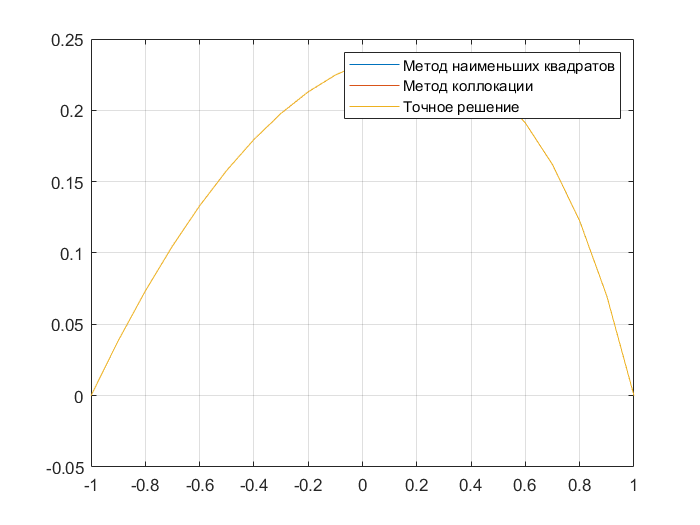

h1 = 1/10;
x1=-1:h1:1;
plot(x1,value(c_ms,coordinate_functions,x1))
hold on
plot(x1,value(c_col,coordinate_functions,x1));
hold on
plot(x1,Y_ex)
hold off
grid on
legend ('Метод наименьших квадратов','Метод коллокации','Точное решение')

При заданном масштабе различия совсем незаметны. Однако, если его изменить, различия становятся более явными.

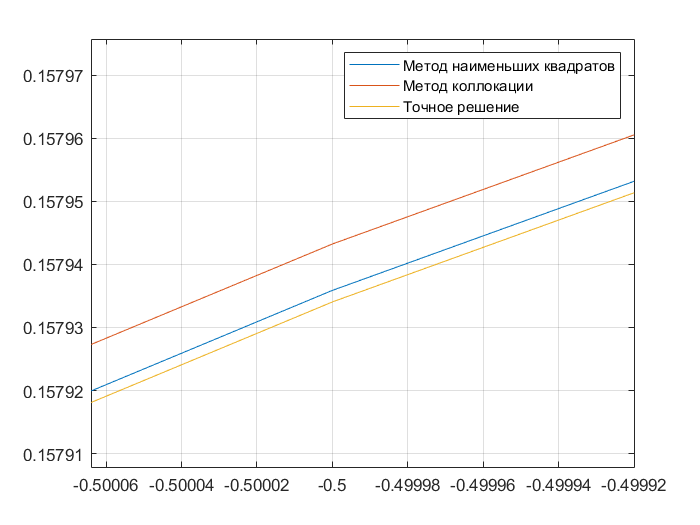

plot(x1,value(c_ms,coordinate_functions,x1))
hold on
plot(x1,value(c_col,coordinate_functions,x1));
hold on
plot(x1,Y_ex)
hold off
grid on
legend ('Метод наименьших квадратов','Метод коллокации','Точное решение')

xlim([-0.500064 -0.499920])
ylim([0.1579079 0.1579757])

## Вспомогательные инструменты

function coordinate_functions = generate_coordinates(n) % Генератор координатных функций
    coordinate_functions = sym(zeros(n,1));
    syms x;
    for i=1:n
        polynom = jacobiP(i-1,1,1,x);
        coordinate_functions(i,1)=(1-x^2)*polynom;
    end
end

% Функция для вычисления значения приближения в заданной точке 
function y_n = value(c,w,arg) 
     y_n= subs(transpose(c)*w,arg);     
end

% Функция для нахождения значения оператора L
function L = L(y)
    syms p q r x; 
    p = (x-7)/(8+3*x);
    q = (1+x/3);
    r = (1- 0.5 * exp(x/2));
    first_order = diff(y);
    second_order= diff(y,2);
    L = p*second_order + q * first_order + r*y;
end
